% H2_tol
% a script to apply tolerances to the fitting function for localization
% This expects localization data in the cdata structure 
% data that was acquired with the 'Hurricane' program
% In an attempt to clean up variables and workspaces I'm using more
% structures in the code than any time previously
clearvars; close all; clc;

% Tolerance parameters

% Red Parameters
mwidth = 6; %marker width for visualization, does not affect data
   tol.r.zlims = [-0.49, 0.49]; % Limit of the absolute value of z-data in pixels
   tol.r.flims = [1,-1];
 tol.r.lat_max = 0.01; % Maximum lateral uncertainty in micrometers
   tol.r.N_tol = [50, 140000000]; % Tolerance on N
  tol.r.offlim = [-10, 125000];
  tol.r.minsnr = 50;
     tol.r.iln = -1;  % lower bound on llv/N
tol.r.frac_lim = 0.3; % Limit on the fractional uncertainty of any value
tol.r.off_frac = 0.5;

% Orange parameters
   tol.o.zlims = [-0.49, 0.49]; % Limit of the absolute value of z-data in pixels
   tol.o.flims = [1,-1];
 tol.o.lat_max = 0.04; % Maximum lateral uncertainty in micrometers
   tol.o.N_tol = [50, 140000000]; % Tolerance on N
  tol.o.offlim = [-10, 125000];
  tol.o.minsnr = 50;
     tol.o.iln = -1;  % lower bound on llv/N
tol.o.frac_lim = 0.5; % Limit on the fractional uncertainty of any value
tol.o.off_frac = 0.5;
tol.dmax = 1;





% File selection
[fname, fpath] = uigetfile('*dast.mat');
cd(fpath)
load([fpath,fname],'cdata','cal','pixw','q');

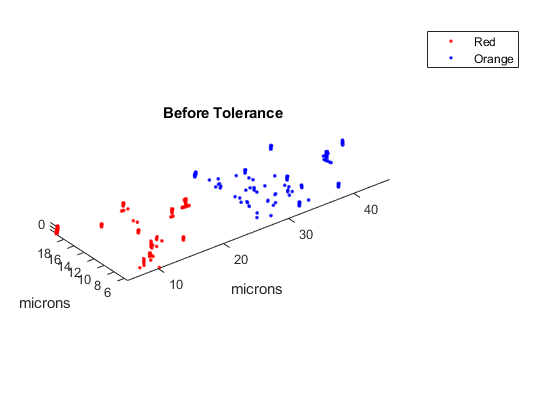

%Setup tolerances
[~, p] = getdz(1,1,cal.red.z_cal, tol.dmax);
tol.r.s_tol = [min(min([p(:,2),p(:,3)])),3*max(max([p(:,2),p(:,3)]))]; % sigma tolerances
[~, p] = getdz(1,1,cal.orange.z_cal,tol.dmax);
tol.o.s_tol = [min(min([p(:,2),p(:,3)])),3*max(max([p(:,2),p(:,3)]))]; % sigma tolerances

if tol.r.flims(2) == -1
    tol.r.flims(2) = max(cdata.red.framenumber);
    tol.o.flims(2) = max(cdata.orange.framenumber);
end
save('Tolfile.mat','tol');

% s_tol = [0.8, 8]; % sigma tolerances
%Eliminate out of view molecue
fnames = fieldnames(cdata.red);
ind = cdata.red.xf < 0 | cdata.red.xf > 200 |cdata.red.yf < 0 | cdata.red.yf > 200;
for i = 1:numel(fnames)
    cdata.red.(fnames{i})(ind,:) = [];
end
try
    cdata.orange.xf = cdata.orange.xf(:);
    cdata.orange.yf = cdata.orange.yf(:);
    ind = cdata.orange.xf < 0 | cdata.orange.xf > 700 | cdata.orange.yf < 0 | cdata.orange.yf > 200;

fnames = fieldnames(cdata.orange);

for i = 1:numel(fnames)
    cdata.orange.(fnames{i})(ind,:) = [];
end
catch
end
%Define fractionals
cdata.red.fr_N =  cdata.red.crlbs(:,3).^0.5./cdata.red.fits(:,3);
cdata.red.fr_sx = cdata.red.crlbs(:,4).^0.5./cdata.red.fits(:,4);
cdata.red.fr_sy = cdata.red.crlbs(:,5).^0.5./cdata.red.fits(:,5);
cdata.red.fr_o =  cdata.red.crlbs(:,6).^0.5./cdata.red.fits(:,6);
cdata.red.ilv = cdata.red.llv(:)./cdata.red.fits(:,3);
cdata.red.eps = abs(cdata.red.fits(:,4)./cdata.red.fits(:,5));
cdata.red.snr =(cdata.red.fits(:,3)./(cdata.red.fits(:,3)+(2*6+1)^2*cdata.red.fits(:,6)).^0.5);
try
cdata.orange.fr_N =  cdata.orange.crlbs(:,3).^0.5./cdata.orange.fits(:,3);
cdata.orange.fr_sx = cdata.orange.crlbs(:,4).^0.5./cdata.orange.fits(:,4);
cdata.orange.fr_sy = cdata.orange.crlbs(:,5).^0.5./cdata.orange.fits(:,5);
cdata.orange.fr_o =  cdata.orange.crlbs(:,6).^0.5./cdata.orange.fits(:,6);
cdata.orange.ilv = cdata.orange.llv(:)./cdata.orange.fits(:,3);
cdata.orange.eps = abs(cdata.orange.fits(:,4)./cdata.orange.fits(:,5));
cdata.orange.snr =(cdata.orange.fits(:,3)./(cdata.orange.fits(:,3)+(2*6+1)^2*cdata.orange.fits(:,6)).^0.5);
catch
end



% Apply Tolerance

% Build Red
ind = cdata.red.fits(:,3) > tol.r.N_tol(1) & cdata.red.fits(:,3) < tol.r.N_tol(2); % Photon Tolerance
ind = ind & cdata.red.snr >= tol.r.minsnr; % Signal to Noise tolerances
ind = ind & abs(cdata.red.framenumber - mean(tol.r.flims)) <= diff(tol.r.flims)/2; % Framenumber tolerances
ind = ind & abs(cdata.red.zf*q-mean(tol.r.zlims)) <= diff(tol.r.zlims)/2; % axial tolerances
ind = ind & abs(cdata.red.fits(:,6)-mean(tol.r.offlim)) <= diff(tol.r.offlim)/2;   % offset tolerances
ind = ind & (abs(cdata.red.fits(:,4)).*abs(cdata.red.fits(:,5))).^0.5 > tol.r.s_tol(1) & (abs(cdata.red.fits(:,4)).*abs(cdata.red.  fits(:,5))).^0.5 < tol.r.s_tol(2); % sigma Tolerance
ind = ind & q*cdata.red.crlbs(:,1).^.5 < tol.r.lat_max & q*cdata.red.crlbs(:,2).^.5 < tol.r.lat_max; % Lateral Uncertainty Tolerance
ind = ind & cdata.red.ilv > tol.r.iln; % llv tolerance
ind = ind & cdata.red.fr_N < tol.r.frac_lim & abs(cdata.red.fr_o) < tol.r.off_frac; % Fraction photon tolerance
ind = ind & cdata.red.fr_sx < tol.r.frac_lim & cdata.red.fr_sy < tol.r.frac_lim; % Fraction width tolerance
rind = ind; % Index represents all molecules that PASS tolerances

% Scream here for sanity
try
% Build Orange
ind = cdata.orange.fits(:,3) > tol.o.N_tol(1) & cdata.orange.fits(:,3) < tol.o.N_tol(2); % Photon Tolerance
ind = ind & cdata.orange.snr >= tol.o.minsnr; % Signal to Noise tolerances
ind = ind & abs(cdata.orange.framenumber - mean(tol.o.flims)) <= diff(tol.o.flims)/2; % Framenumber tolerances
ind = ind & abs(cdata.orange.zf*q-mean(tol.o.zlims)) <= diff(tol.o.zlims)/2; % axial tolerances
ind = ind & abs(cdata.orange.fits(:,6)-mean(tol.o.offlim)) <= diff(tol.o.offlim)/2;   % offset tolerances
ind = ind & (abs(cdata.orange.fits(:,4)).*abs(cdata.orange.fits(:,5))).^0.5 > tol.o.s_tol(1) & (abs(cdata.orange.fits(:,4)).*abs(cdata.orange.  fits(:,5))).^0.5 < tol.o.s_tol(2); % sigma Tolerance
ind = ind & q*cdata.orange.crlbs(:,1).^.5 < tol.o.lat_max & q*cdata.orange.crlbs(:,2).^.5 < tol.o.lat_max; % Lateral Uncertainty Tolerance
ind = ind & cdata.orange.ilv > tol.o.iln; % llv tolerance
ind = ind & cdata.orange.fr_N < tol.o.frac_lim & abs(cdata.orange.fr_o) < tol.o.off_frac; % Fraction photon tolerance
ind = ind & cdata.orange.fr_sx < tol.o.frac_lim & cdata.orange.fr_sy < tol.o.frac_lim; % Fraction width tolerance
oind = ind; % Index represents all molecules that PASS tolerances
catch
end
% save('Tolfile.mat','flims','minsnr','zlims','lat_max','N_tol','s_tol','iln','frac_lim','off_frac','offlim');

notind = logical(1-ind);
% Setting up our figure
r = str2num(fname(strfind(fname,'_r')+3));
r=0;
zfr = func_shift_correct(cdata.red.zf*q,cdata.red.framenumber,r);
try
zfo = func_shift_correct(cdata.orange.zf*q,cdata.orange.framenumber,r);
catch
end
% zf = ncoords(:,3)*q;

%Plot spatial Data pre tolerance
plot3(cdata.red.xf*q,cdata.red.yf*q,cdata.red.zf*q,'.r','MarkerSize',mwidth);
hold on
try
plot3(cdata.orange.xf*q,cdata.orange.yf*q,cdata.orange.zf*q,'.b','MarkerSize',mwidth);
catch lsterr
end
legend('Red','Orange')
hold off
% s.MarkerFaceColor = s.MarkerEdgeColor;
% colormap('jet')
xlabel('microns');
ylabel('microns');
axis equal
title('Before Tolerance')

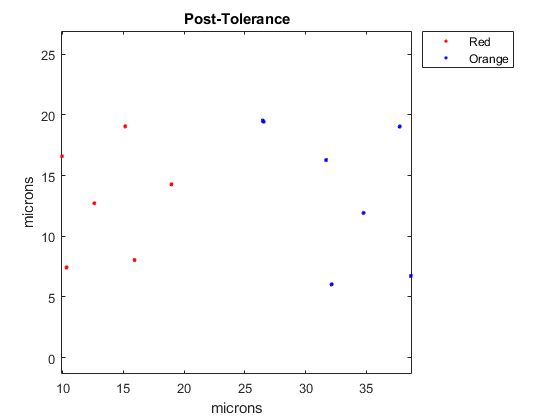

plot( cdata.red.xf(rind)*q,cdata.red.yf(rind)*q,'.r','MarkerSize',mwidth);
hold on
try
plot(cdata.orange.xf(oind)*q,cdata.orange.yf(oind)*q,'.b','MarkerSize',mwidth);
catch
end
legend('Red','Orange')
hold off
xlabel('microns');
ylabel('microns');
axis equal
title('Post-Tolerance')

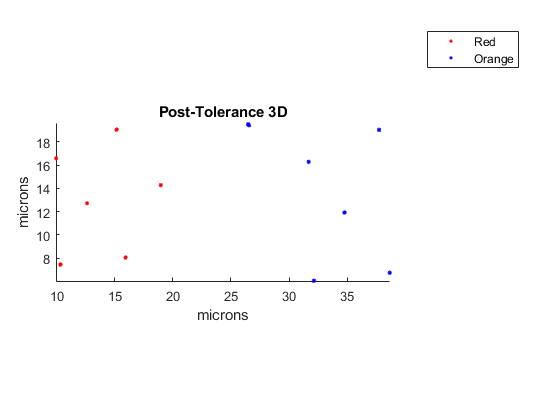

plot3(cdata.red.xf(rind)*q,cdata.red.yf(rind)*q,zfr(rind),'.r','MarkerSize',mwidth);
hold on
try
plot3( cdata.orange.xf(oind)*q,cdata.orange.yf(oind)*q,zfo(oind),'.b','MarkerSize',mwidth);
catch
    
end
title('Post-Tolerance 3D');
legend('Red','Orange')
hold off
xlabel('microns');
ylabel('microns');
zlabel('microns');
axis equal

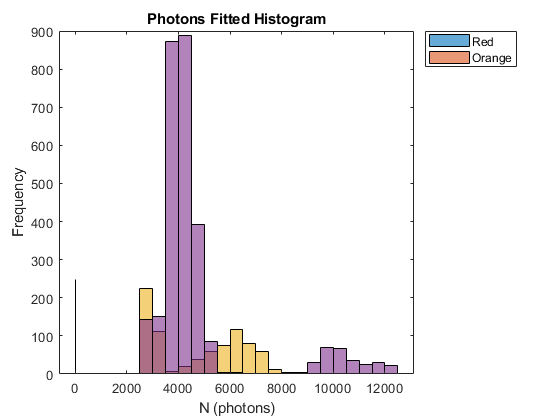


histogram(cdata.red.zf(rind)*q);
hold on
try
histogram(cdata.orange.zf(oind)*q);
catch
end
legend('Red','Orange')
xlabel('Z-position(um)')
ylabel('Frequency')
title('Z-Position Histogram')


histogram(cdata.red.fits(rind,3));
hold on
try
histogram(cdata.orange.fits(oind,3));
catch
end
hold off
legend('Red','Orange')
xlabel('N (photons)')
ylabel('Frequency')
title('Photons Fitted Histogram')

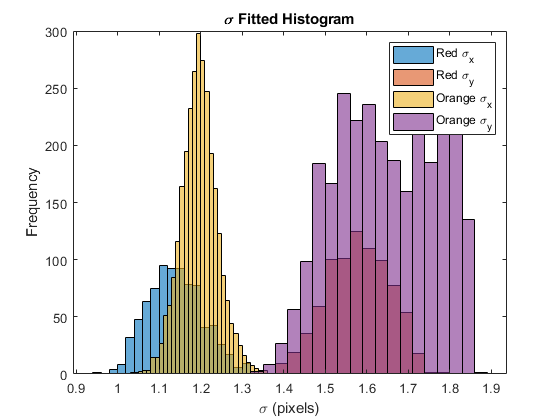



histogram(cdata.red.fits(rind,4));
hold on
histogram(cdata.red.fits(rind,5));
try
histogram(cdata.orange.fits(oind,4));
histogram(cdata.orange.fits(oind,5));
catch
end
hold off
legend('Red \sigma_x','Red \sigma_y', 'Orange \sigma_x','Orange \sigma_y')
xlabel('\sigma (pixels)')
ylabel('Frequency')
title('\sigma Fitted Histogram')

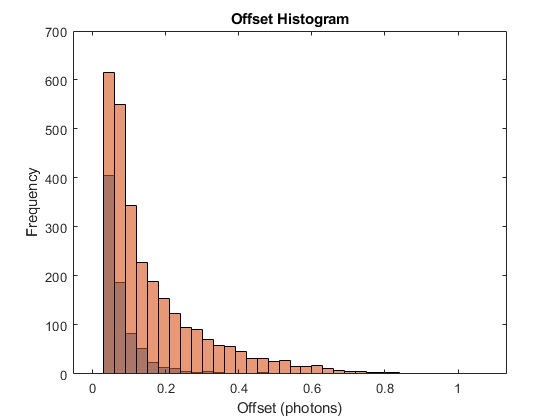



histogram(cdata.red.fits(rind,6));
hold on
histogram(cdata.orange.fits(oind,6));
hold off
xlabel('Offset (photons)')
ylabel('Frequency')
title('Offset Histogram')

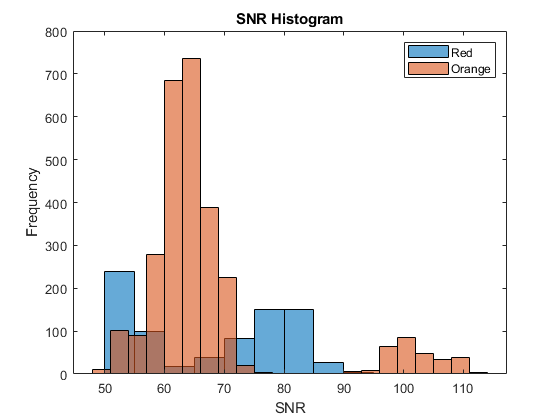



histogram(cdata.red.snr(rind));
hold on
histogram(cdata.orange.snr(oind));
hold off
legend('Red','Orange')
xlabel('SNR')
ylabel('Frequency')
title('SNR Histogram')

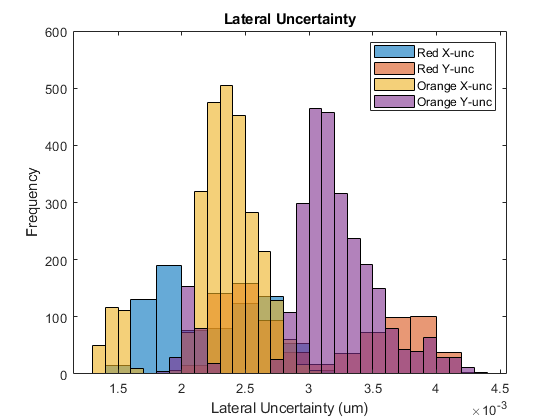



histogram(cdata.red.crlbs(rind,1).^0.5*q)
hold on
histogram(cdata.red.crlbs(rind,2).^0.5*q)
histogram(cdata.orange.crlbs(oind,1).^0.5*q)
histogram(cdata.orange.crlbs(oind,2).^0.5*q)
hold off
legend('Red X-unc','Red Y-unc','Orange X-unc','Orange Y-unc');
xlabel('Lateral Uncertainty (um)')
ylabel('Frequency')
title('Lateral Uncertainty');

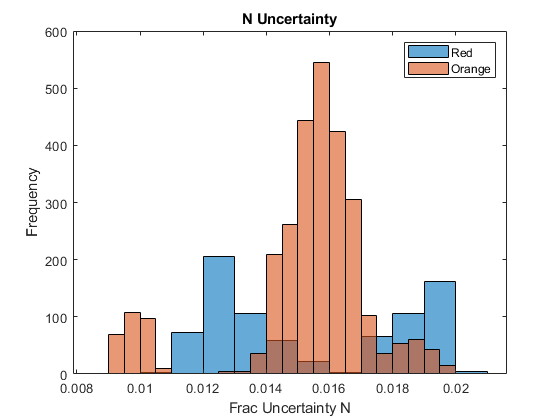




histogram(cdata.red.fr_N(rind))
hold on
histogram(cdata.orange.fr_N(oind))
hold off
legend('Red','Orange')
xlabel('Frac Uncertainty N')
ylabel('Frequency')
title('N Uncertainty');

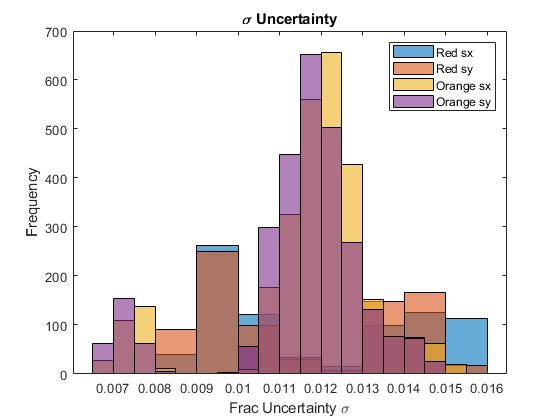

clear t22


histogram(cdata.red.fr_sx(rind))
hold on
histogram(cdata.red.fr_sy(rind))
histogram(cdata.orange.fr_sx(oind))
histogram(cdata.orange.fr_sy(oind))
hold off
legend('Red sx','Red sy','Orange sx','Orange sy')
xlabel('Frac Uncertainty \sigma')
ylabel('Frequency')
title('\sigma Uncertainty');

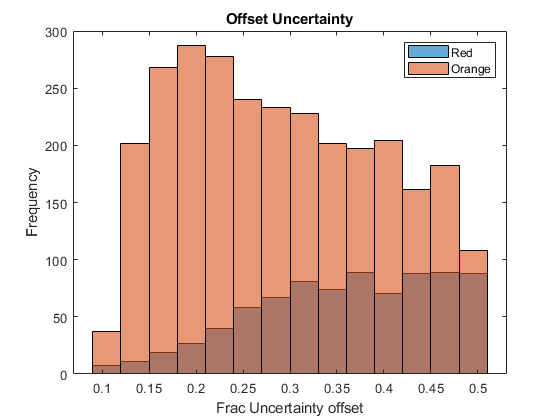




histogram(cdata.red.fr_o(rind))
hold on
histogram(cdata.orange.fr_o(oind))
hold off
legend('Red','Orange')
xlabel('Frac Uncertainty offset')
ylabel('Frequency')
title('Offset Uncertainty');

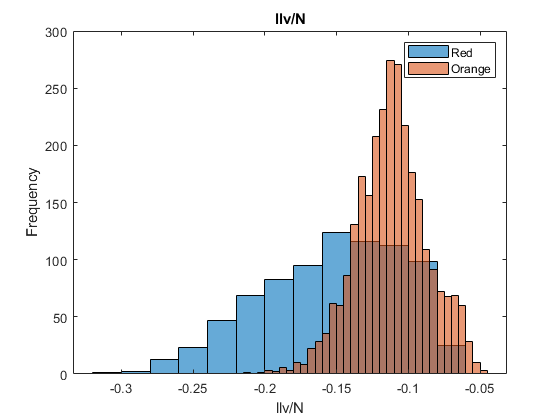

clear t24


histogram(cdata.red.ilv(rind))
hold on
histogram(cdata.orange.ilv(oind))
hold off
legend('Red','Orange')
xlabel('llv/N')
ylabel('Frequency')
title('llv/N');

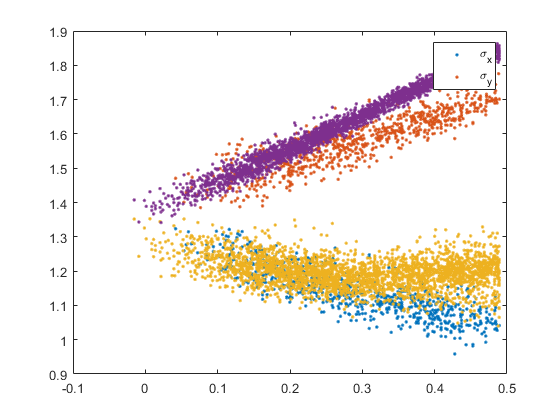




plot(cdata.red.zf(rind)*q,cdata.red.fits(rind,4),'.')
hold on
plot(cdata.red.zf(rind)*q,cdata.red.fits(rind,5),'.')
plot(cdata.orange.zf(oind)*q,cdata.orange.fits(oind,4),'.')
plot(cdata.orange.zf(oind)*q,cdata.orange.fits(oind,5),'.')
hold off
legend('\sigma_x','\sigma_y')